% making the value of heaviside() at origin equal to 1
sympref('HeavisideAtOrigin', 1);
u = @(n) heaviside(n);

% defining the DTFT function
dtft = @(xn, n, w) xn * exp(-1j .* (n' * w));

% defining discrete time Inverse Fourier Transform
dtift = @(Xw, w, n) (Xw * exp(1j .* (w' * n))) ./ length(w);

% defining range of frequencies (omega) from -pi to +pi
w = -pi:0.01:pi;
omega_labels = ["-\pi", "-3\pi/4", "-\pi/2", "-\pi/4", 0, "\pi/4", "\pi/2", "3\pi/4", "\pi"];

The Transfer function of the filter is given by:


$$H(z) = \frac{(z-1)(z+1)(z-i)(z+i)}{z^4} = 1 - z^{-4}$$


Replacing $z$ with $e^{j\omega}$ to get the Fourier Transform of the filter, i.e. it's frequency response,


$$H(e^{j\omega}) = 1 - e^{-j4\omega}$$


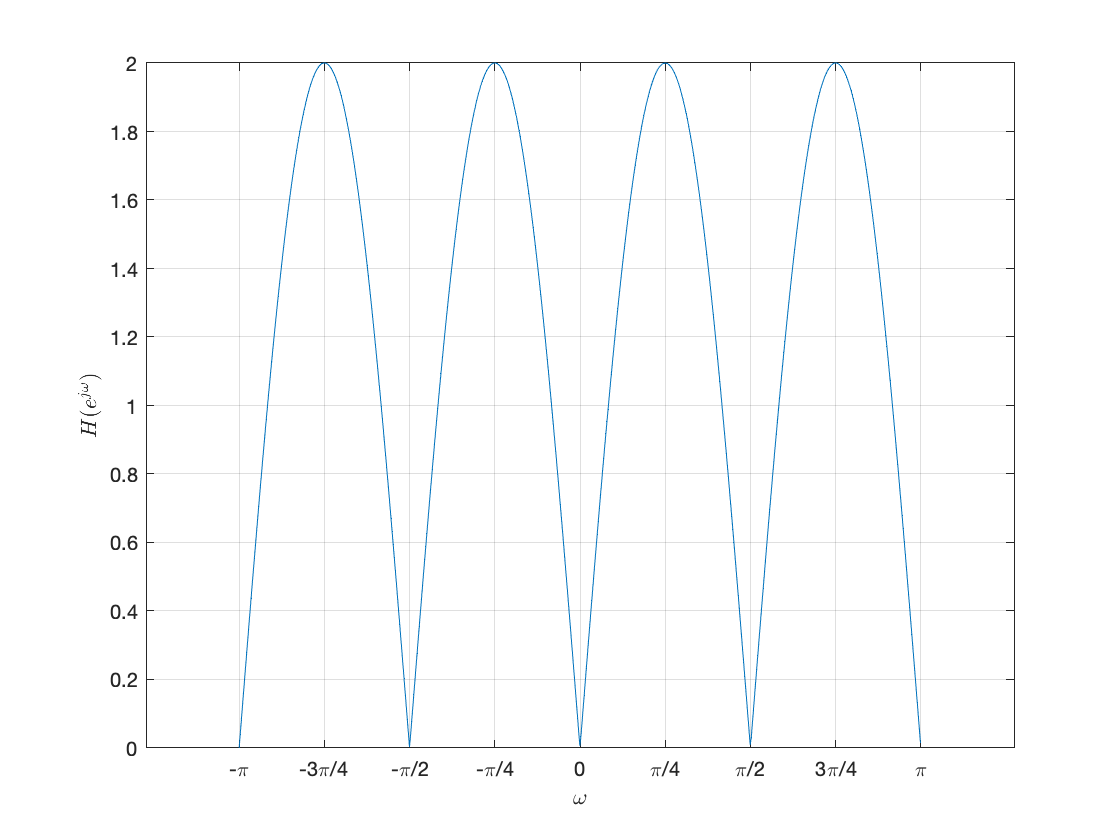

H = @(w) 1 - exp(-4j * w);
Hw = H(w);

plot(w, abs(Hw));
xlabel("\omega"); ylabel("$H(e^{j\omega})$", "Interpreter","latex");
xticks(-pi:pi/4:pi); xticklabels(omega_labels); grid();

% Attempting to design a notch filter


$$H(z) = \frac{(z-1)(z-i)(z+1)(z+i)}{(z-0.9)(z-i0.9)(z+0.9)(z+i0.9)} $$


         
$$= \frac{z^4 - 1}{z^4 - 0.6561}$$


Replacing $z$ with $e^{l\omega}$,


$$H(e^{j\omega}) = \frac{e^{j4\omega} - 1}{e^{j4\omega} - 0.6561}$$


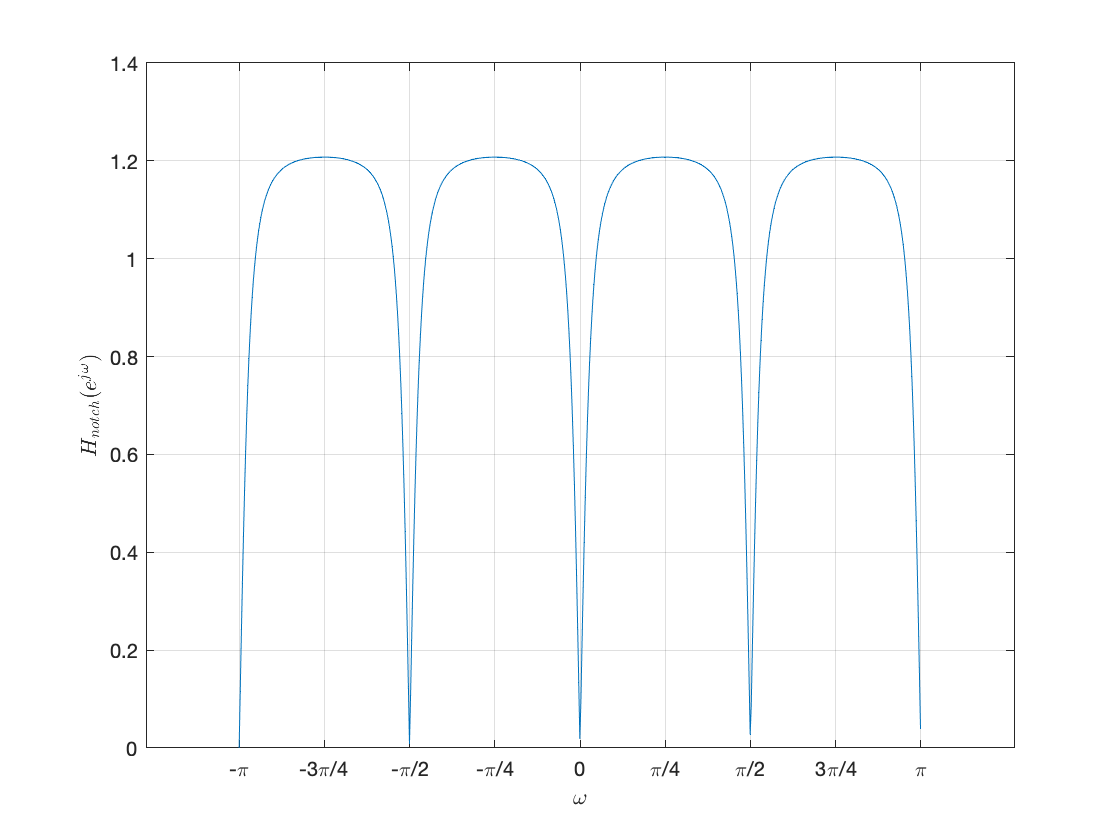

H_notch = @(w) (exp(1j * 4 * w) - 1) ./ (exp(1j * 4 * w) - 0.6561);
H_notch_w = H_notch(w);

plot(w, abs(H_notch_w));
xlabel("\omega"); ylabel("$H_{notch}(e^{j\omega})$", "Interpreter","latex");
xticks(-pi:pi/4:pi); xticklabels(omega_labels); grid();

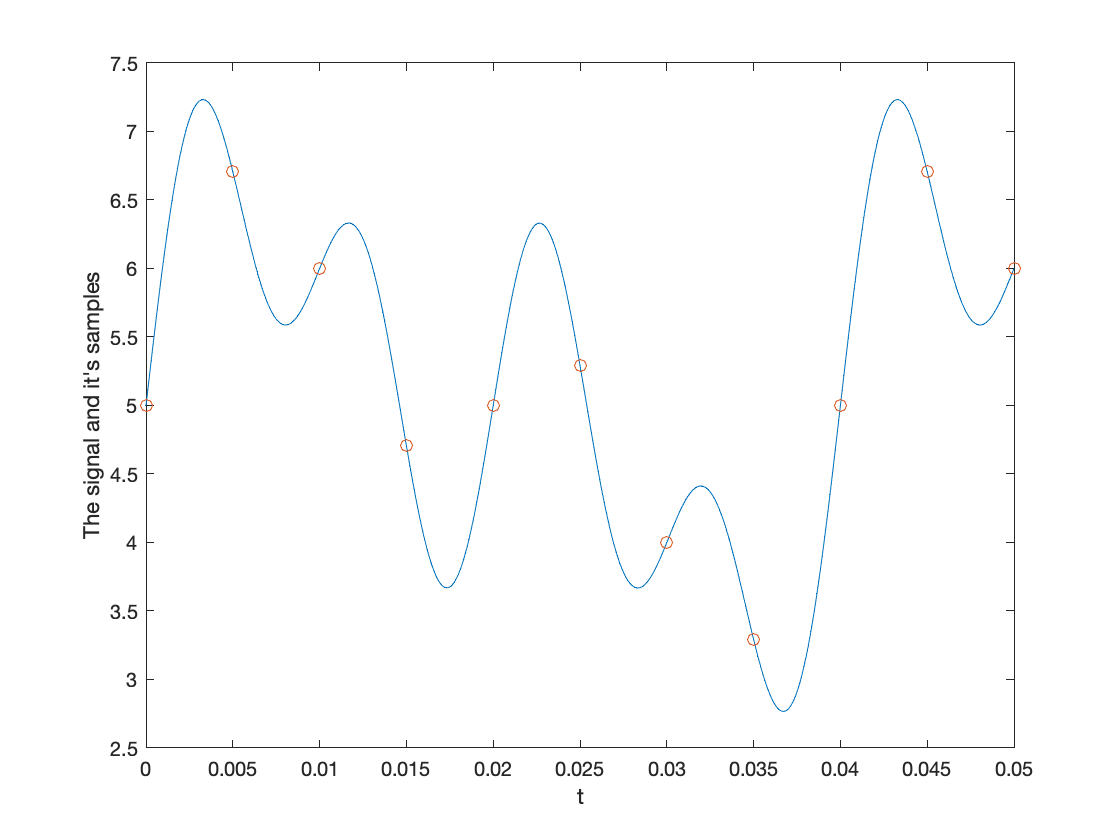

% sampling frequency 200Hz
fs = 200;
Ts = 1/fs;

% test signal having sinusoids of frequencies 25Hz, 50Hz, 100Hz, and a DC component
main_signal = @(t) sin(2*pi*25*t);
noise = @(t) 5 + sin(2*pi*50*t) + sin(2*pi*100*t);
signal_continuous = @(t) noise(t) + main_signal(t);

% discrete samples of the signal
signal_discrete = @(n) signal_continuous(n * Ts);

t = 0:0.00005:0.05;
xt = signal_continuous(t);
n = 0:10;
xn = signal_discrete(n);

plot(t, xt, n*Ts, xn, "o");
xlabel("t"); ylabel("The signal and it's samples");

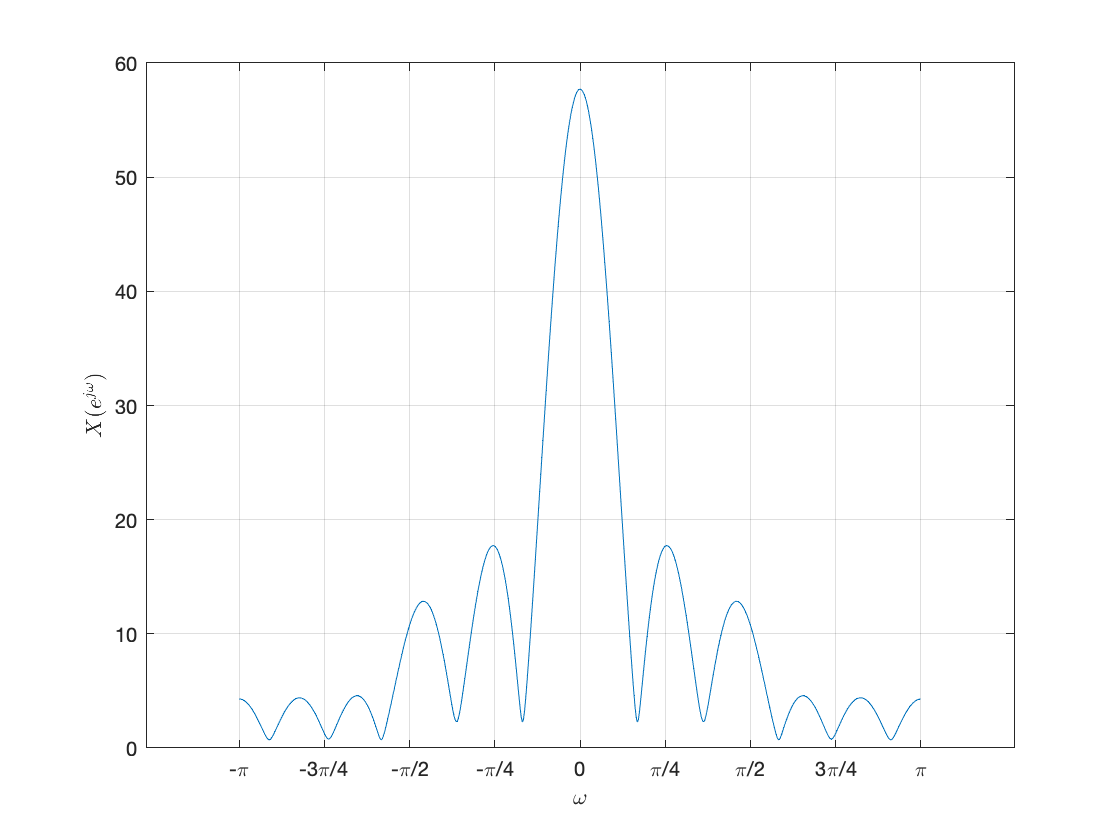

% Frequency spectrum of the signal
Xw = dtft(xn, n, w);
plot(w, abs(Xw));
xlabel("\omega"); ylabel("$X(e^{j\omega})$", "Interpreter","latex");
xticks(-pi:pi/4:pi); xticklabels(omega_labels); grid();

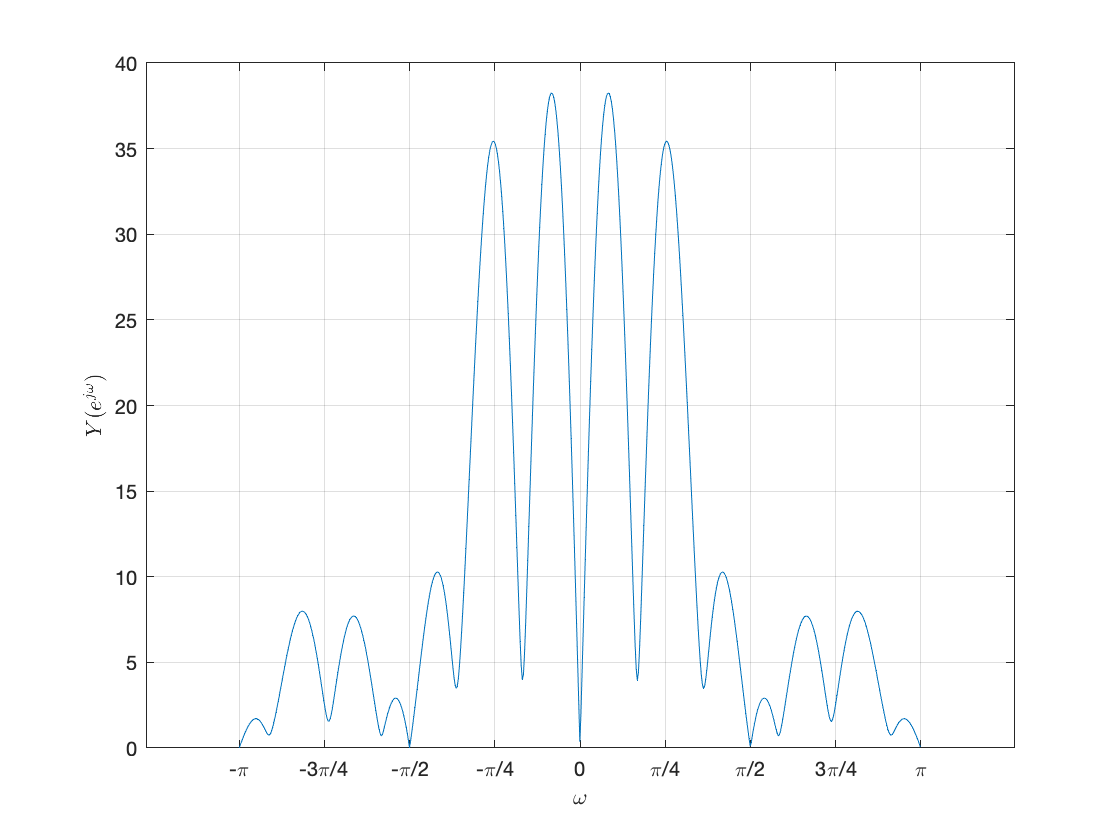

% Filtering
Yw = Xw .* Hw;
% Yw = Xw .* H_notch_w;
plot(w, abs(Yw));
xlabel("\omega"); ylabel("$Y(e^{j\omega})$", "Interpreter","latex");
xticks(-pi:pi/4:pi); xticklabels(omega_labels); grid();

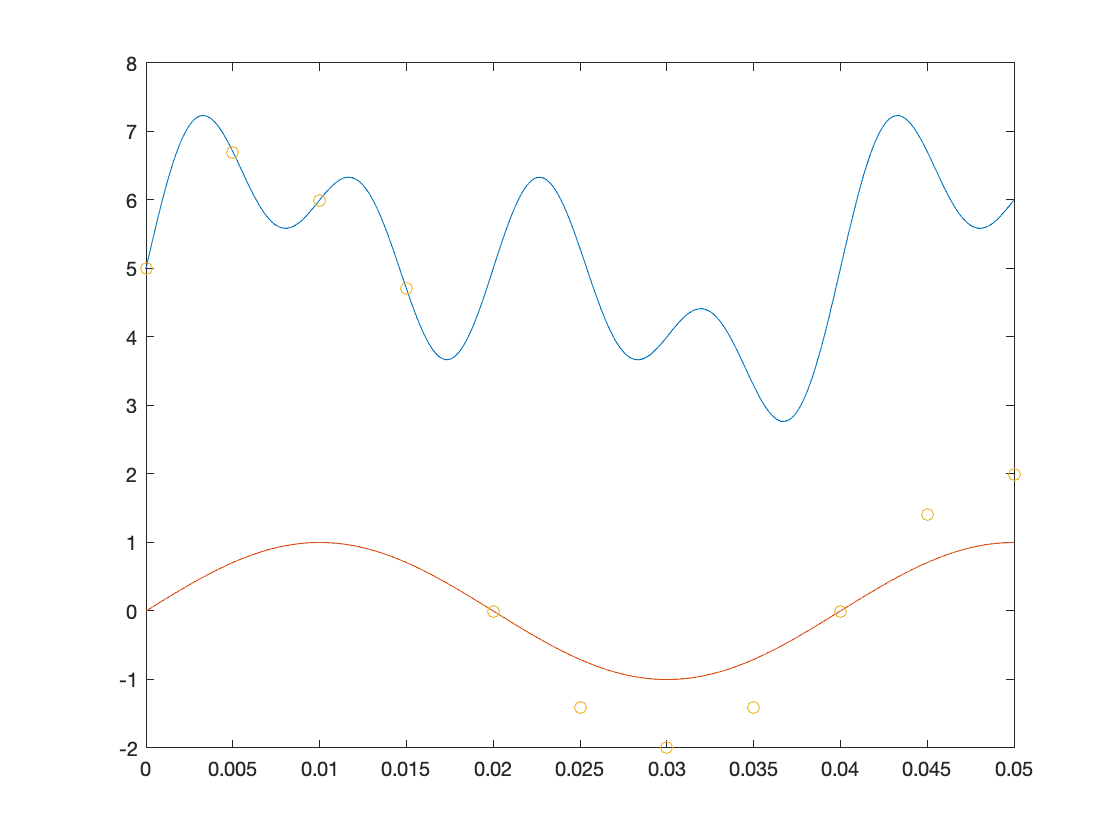

yn = real(dtift(Yw, w, n));
plot(t, xt, t, main_signal(t), n*Ts, yn, "o");